***Integrantes***:

- Naysla tatiana torres Cortes

- Ariel David Herrera Ahumda

# MÉTODO SIMPSON 3/8

**Ejercicio 1**

%datos iniciales
a=2;
b=5;
%Determinar el valor de h
h =ValorH(a,b);
%Determinar los puntos
cotaMin=a;
cotaMinh=cotaMin+h;
cotaMin2h=cotaMinh+h;
cotaMin3h=cotaMin2h+h;
%validar funcion en cada punto
f_cotaMin=EvaluarFuncion(cotaMin);
f_cotaMinh=3*EvaluarFuncion(cotaMinh);
f_cotaMin2h=3*EvaluarFuncion(cotaMin2h);
f_cotaMin3h=EvaluarFuncion(cotaMin3h);
%Sumatoria de los puntos 
Sum = f_cotaMin+f_cotaMinh+f_cotaMin2h+f_cotaMin3h;
%Hallar valor de la integral
v = ValorIntegral(Sum,h)

v = 7.3180

strcat('El resltado es :',num2str(v))

ans = 'El resltado es :7.318'

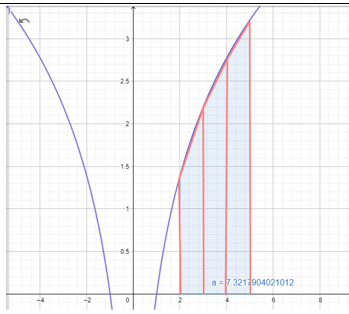

***FUNCIONES***  

function [h]=ValorH(a,b)
  h= (b-a)/3;
end
function f = EvaluarFuncion(x)    
    f = log(x^2);
end
function [v]=ValorIntegral(sum,h)    
    v= (3*h/8)*sum;
end

